# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments.

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 3 - Channel Coding`

### `Digital Communication System Schematic`

# 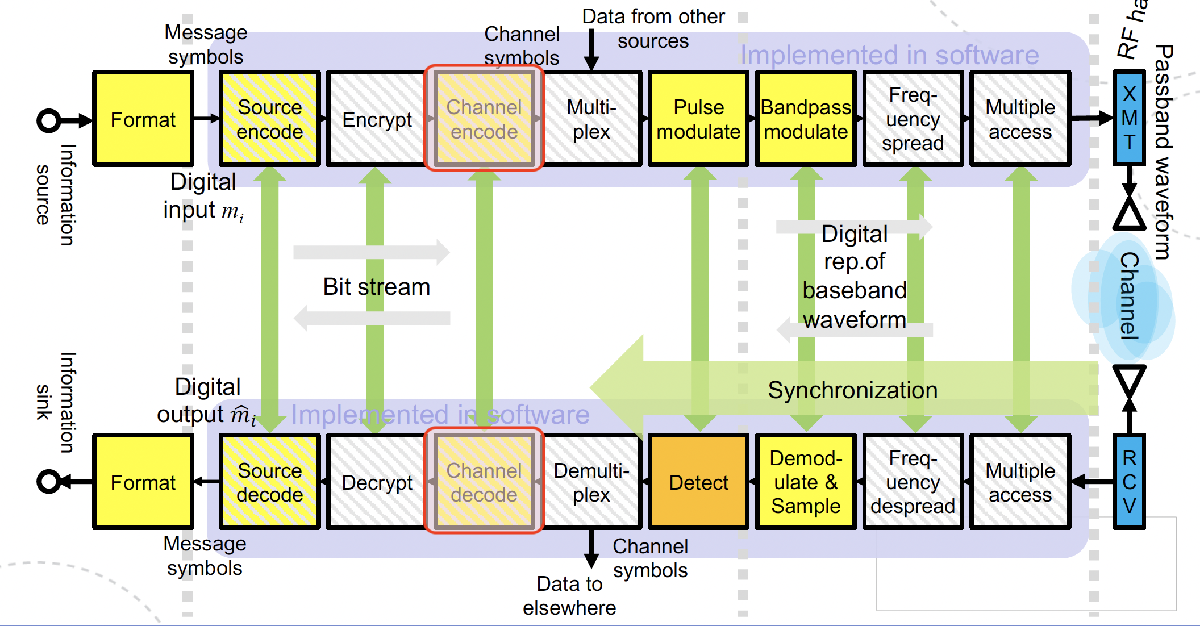

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

### `Course Content`

- Coding Gain

- Convolutional Codes

- Cyclic redundancy check

- Bit interleaved coded modulation

#### `Task 1 : Hamming Code`

This task illustrates the principle of *block codes*. 

- Generator Matrix

- Parity Check Matrix

- Syndrome

Recomended reading: Section 6.4 *Linear Block Codes *in *Digital Communications, Sklar*

% Tip: Use MatLab inbuilt functions whenever possible 


% Define message length k and codeword length n 
n = 7; k = 4;     

% Generate random binary message of length k
data = randi([0 1], k, 1)';


% Generate parity check matrix and generator matrix using hammgen()
[H, G, n, k] = hammgen(3);

% Encode the message using encode()
enc_data = encode(data, n, k);
%  Use the first column of the codes STANDARD ARRAY to construct the error
%  pattern -> syndrome LUT
LUT = containers.Map( ...
    'keyType', 'char', ...
    'ValueType', 'any');
e = zeros(1, n);
s = mod(H * e', 2);
LUT(num2str(s')) = e;

for i = 1:n
    e = zeros(1,n);
    e(i) = 1;
    s = mod(H * e', 2);
    LUT(num2str(s')) = e;
end
% Introduce 1-bit errors at different positions in the codeword and calculate the
% syndrome of the error
receiveBit = enc_data;
flipBit = 3;

% Flip 1 bit
receiveBit(flipBit) = mod(receiveBit(flipBit) + 1, 2);

% Decode using created LUT & check if 1-bit error can be successfully
% decoded
s_bit = mod(H * receiveBit',2 );
num2str(s_bit);
e_hat = LUT(num2str(s_bit'));
correctBit = mod(receiveBit + e_hat, 2);
decoded_1bit = correctBit(logical(sum(G, 1) == 1));                                                      
  fprintf('Original data:     %s\n', num2str(data));   

Original data:     0  1  0  1


  fprintf('Sendt bit:       %s\n', num2str(receiveBit));

Sendt bit:       1  1  1  0  1  0  1


  fprintf('Decoded (1-bit):   %s\n', num2str(decoded_1bit));                                                     

Decoded (1-bit):   0  1  0  1


  fprintf('1-bit error corrected: %d\n', isequal(data, decoded_1bit));

1-bit error corrected: 1


% ------------------------------------------------- %

% Flip 2 bits at different positions and check if the erraneous codeword
% can be successfully decoded
recivedData2 = enc_data;
recivedData2(1) = mod(recivedData2(1) + 1, 2);
recivedData2(6) = mod(recivedData2(6) + 1, 2);

s_bit = mod(H * recivedData2', 2)

s_bit =      0
     1
     1


e_hat = LUT(num2str(s_bit'))

e_hat =      0     0     0     0     1     0     0


corrected2 = mod(recivedData2 + e_hat, 2);
decoded2 = corrected2(logical(sum(G,1) == 1))

decoded2 =      0     0     1     1


recivedData2

recivedData2 =      0     1     0     0     1     1     1


data

data =      0     1     0     1


% Decode with Matlab inbuilt functions and confirm your findings from above


#### `Task 2 : Convolutional Encoder & Decoder`

- Convolutional Encoding

- Convolutional Code Parameters

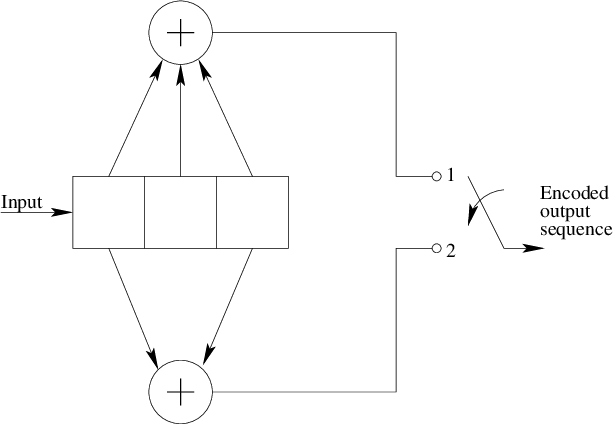

Determine the convolutional coding parameters from the schematic above. Then implement the convolutional encoder for a binary sequence of your choice. 

If you decide to use a non continous message bit stream (i.e., a message of specific length) *flush *the registers. 

*(refer to p. 378ff Digital Communcations, Sklar)*

%% Task 2 – Convolutional Encoder & Viterbi Decoder
clear; clc;

K       = 3;
trellis = poly2trellis(K, [7 5]);
tblen   = 5 * K;

msg = randi([0 1], 1, 100);

msg_flushed = [msg, zeros(1, K-1)];
enc = convenc(msg_flushed, trellis);
enc = enc(:)';

tx = 1 - 2*double(enc);
noise_std = 0.8;   % higher = more noise, try 0.1, 0.5, 1.0, 2.0
rx = tx + noise_std * randn(size(tx));
fprintf('Bit errors before decoding: %d / %d\n', ...
    sum(double(rx < 0) ~= enc), length(enc));

Bit errors before decoding: 20 / 204




% --- Hard decision Viterbi ---
n_sym      = length(rx) / 2;
tblen_safe = min(tblen, n_sym);

dec_hard = vitdec(double(rx < 0), trellis, tblen_safe, 'trunc', 'hard');
dec_hard = dec_hard(1:length(msg));
fprintf('Bit errors after hard Viterbi: %d / %d\n', sum(msg ~= dec_hard), length(msg));

Bit errors after hard Viterbi: 5 / 100



% --- Soft decision Viterbi ---
dec_soft = vitdec(softQuantize(rx, 3), trellis, tblen_safe, 'trunc', 'soft', 3);
dec_soft = dec_soft(1:length(msg));
fprintf('Bit errors after soft Viterbi: %d / %d\n', sum(msg ~= dec_soft), length(msg));

Bit errors after soft Viterbi: 0 / 100



% --- Helper ---
function q = softQuantize(rx, nsdec)
    levels     = 2^nsdec - 1;
    clip       = 3.0;
    rx_clipped = max(-clip, min(clip, rx));
    q          = round((1 - rx_clipped/clip) / 2 * levels);
    q          = max(0, min(levels, q));
end


#### `Task 3 : Cyclic Redundancy Check - CRC`

Now use a CRC encoder on your message.

Obtain an estimate for the error detection capability of the CRC, i.e. what is the probability of missed error detection of the CRC, and the overhead introduced.

% Original message
msg_len = 100;
msg = randi([0 1], msg_len, 1);
disp('Original message:');
disp(msg.');

% CRC encode
crcGen = comm.CRCGenerator([1 0 0 1 1]);
crcDet = comm.CRCDetector([1 0 0 1 1]);
msg_crc = crcGen(msg);

disp('Message after CRC encoding:');
disp(msg_crc.')
fprintf('Original length: %d bits\n', length(msg));
fprintf('Length after CRC: %d bits\n', length(msg_crc));

% Convolutional encode (Task 2 function, or matlab built-in function)
trellis = poly2trellis(3, [7 5]);  
coded = convenc(msg_crc, trellis);

disp('Convolutionally encoded sequence:');
disp(coded.');

% Simulate channel — introduce errors
flip_prob = 0.02;
rx = coded;
error_positions = rand(size(rx)) < flip_prob;
rx(error_positions) = ~rx(error_positions);

disp('Received sequence after channel errors:');
disp(rx.');

% Viterbi decode
tblen = 35; 
decoded = vitdec(rx, trellis, tblen, 'trunc', 'hard');

decoded = decoded(1:length(msg_crc)); % Keep only the expected number of bits
disp('Decoded sequence after Viterbi:');
disp(decoded.');

% CRC check — did Viterbi recover everything correctly?
[recoverd_msg, crc_error] = crcDet(decoded);
disp('Recovered message after CRC removal:');
disp(recoverd_msg.');

if crc_error == 0
    disp('CRC check passed: No error detected.');
else
    disp('CRC check failed: Error detected.');
end

% Estimate missed error probability and overhead

num_trials = 1000;
num_error_events = 0;
num_missed = 0;

for t = 1:num_trials
    
    % Original message
    msg = randi([0 1], msg_len, 1);
    
    % CRC encode
    msg_crc = crcGen(msg);
    
    % Convolutional encode
    coded = convenc(msg_crc, trellis);
    
    % Simulate channel - introduce errors
    rx = coded;
    error_positions = rand(size(rx)) < flip_prob;
    rx(error_positions) = ~rx(error_positions);
    
    % Viterbi decode
    decoded = vitdec(rx, trellis, tblen, 'trunc', 'hard');
    decoded = decoded(1:length(msg_crc));
    
    % CRC check
    [recovered_msg, crc_error] = crcDet(decoded);
    
    % Check if decoded block was actually wrong
    if any(decoded ~= msg_crc)
        num_error_events = num_error_events + 1;
        
        % CRC missed the error
        if crc_error == 0
            num_missed = num_missed + 1;
        end
    end
end

if num_error_events > 0
    P_missed = num_missed / num_error_events;
else
    P_missed = 0;
end

crc_bits = length(msg_crc) - length(msg);
overhead_fraction = crc_bits / length(msg);
overhead_percent = 100 * overhead_fraction;

disp('--- CRC performance estimates ---');
fprintf('CRC bits added: %d\n', crc_bits);
fprintf('CRC overhead fraction: %.4f\n', overhead_fraction);
fprintf('CRC overhead percent: %.2f%%\n', overhead_percent);
fprintf('Number of error events after Viterbi: %d\n', num_error_events);
fprintf('Number of missed detections: %d\n', num_missed);
fprintf('Estimated probability of missed error detection: %.6f\n', P_missed);

`Task 4: Interleaving`

Realise a system that utilises convolutional coding and eventually cyclic redundancy checks to correct and detect errors in transmission.

Document the minimum separation achieved by the interleaver.

% Message + CRC


% Convolutional encoding


% Interleaving


% 16-QAM modulation. Note: needs groups of 4 bits, Matlab function qammod()


% Channel — AWGN


% Demodulation


% De-interleaving


% Viterbi decoding


% CRC check


% BER count



Check BER at 10dB, and 5dB

#### `Task 5: Coding Gain`

Compare the BER vs SNR performance of     

- Hamming codes

- Convolutional codes w/ hard-, and soft decoding

This is an unguided exercises. It is recommended to use Matlab inbuilt functions wherever possible. 

% Implementation
